# State Space

clear;close all;clc

syms k c_1 c_2 I_1 I_2 t tau_1(t) tau_2(t) theta_1(t) theta_2(t) Y

dth_1   = diff(theta_1,t,1);
d2th_1  = diff(theta_1,t,2);
dth_2   = diff(theta_2,t,1);
d2th_2  = diff(theta_2,t,2);
    
M_cm1 = -c_1*dth_1 + k*theta_2 + c_2*dth_2 + tau_1(t) == I_1*d2th_1;
SS_1 = d2th_1 == expand(subs(solve(subs(M_cm1,d2th_1,Y),Y),Y,d2th_1))

$$SS\_1(t) = \frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=\frac{\tau_{1}\left(t\right)}{I_{1}}-\frac{c_{1}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{I_{1}}+\frac{c_{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{I_{1}}+\frac{k\,\theta_{2}\left(t\right)}{I_{1}}$$

M_cm2 = -k*theta_2 - c_2*dth_2 +tau_2(t) == I_2*(d2th_1 + d2th_2);
SS_2 = subs(M_cm2,d2th_1,rhs(SS_1));
SS_2  = d2th_2 == simplify(expand(subs(solve(subs(SS_2,d2th_2,Y),Y),Y,d2th_2)))

$$SS\_2(t) = \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=\frac{\tau_{2}\left(t\right)}{I_{2}}-\frac{\tau_{1}\left(t\right)}{I_{1}}+\frac{c_{1}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{I_{1}}-\frac{c_{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{I_{1}}-\frac{c_{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{I_{2}}-\frac{k\,\theta_{2}\left(t\right)}{I_{1}}-\frac{k\,\theta_{2}\left(t\right)}{I_{2}}$$

## Plant Model:


$$\left\lbrack \begin{array}{c}
{\theta^˙ }_1 \left(t\right)\\
{\theta^¨ }_1 \left(t\right)\\
{\theta^˙ }_2 \left(t\right)\\
{\theta^¨ }_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & -\frac{c_1 }{I_1 } & \frac{k}{\;I_1 } & \frac{c_2 }{I_1 }\\
0 & 0 & 0 & 1\\
0 & \frac{c_1 }{I_1 } & -k\left(\frac{1}{I_1 }+\frac{1}{I_2 }\right) & -c_2 \left(\frac{1}{I_1 }+\frac{1}{I_2 }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta_1 \left(t\right)\\
{\theta^˙ }_1 \left(t\right)\\
\theta_2 \left(t\right)\\
{\theta^˙ }_2 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
\frac{1}{I_1 } & 0\\
0 & 0\\
-\frac{1}{I_1 } & \frac{1}{I_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\tau_1 \left(t\right)\\
\tau_2 \left(t\right)
\end{array}\right\rbrack$$


wn = 50; % head natural frequency [rad/s]
z = 1.2; % head damping ratio []
% m_1 = 0.8418e-3; % body mass [kg]
% m_2 = 0.0895e-3; % head mass [kg]
I_1 = 0.5665*(10^(-3))^(3); % body inertia about rotation point [kg*m^2]
I_2 = 0.0895*(10^(-3))^(3); % head inertia about rotation point [kg*m^2]
k = wn^(2)*I_2; % head stiffness [N*m/rad]
cc = 2*sqrt(k*I_2); % head critical damping [N*m*s/rad]
c_2 = z*cc; % head damping [N*m*s/rad]
c_1 = 5*c_2; % body damping [N*m*s/rad]

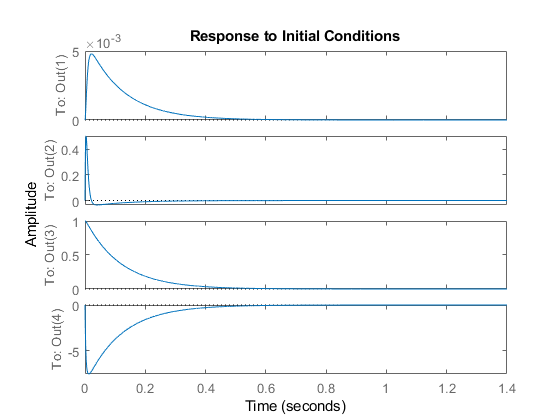


A = [0 1 0 0;...
     0 -c_1/I_1 k/I_1 c_2/I_1;...
     0 0 0 1;...
     0 c_1/I_1 -k*(I_1^-(1) + I_2^(-1)) -c_2*(I_1^-(1) + I_2^(-1))];
B = [0 0;...
     1/I_1 0;...
     0 0;...
     -1/I_1 1/I_2];
 C = eye(size(A));
 D = zeros(size(B));
 StateName = {'theta_1','dtheta_1','theta_2','dtheta_2'};
 SYS = ss(A,B,C,D,'StateName',StateName,'StateUnit',{'rad','rad/s','rad','rad/s'},'TimeUnit','seconds','InputName',{'tau_1','tau_2'});
 
 initial(SYS,[0 0 1 0])